theta = 0:179;
F2 = iradon(File2, theta, 'linear', 'Ram-Lak', 1, 512);

I2 = imresize(F2,0.5);

% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I2) / 2

translation =    -8.4968  -18.9205


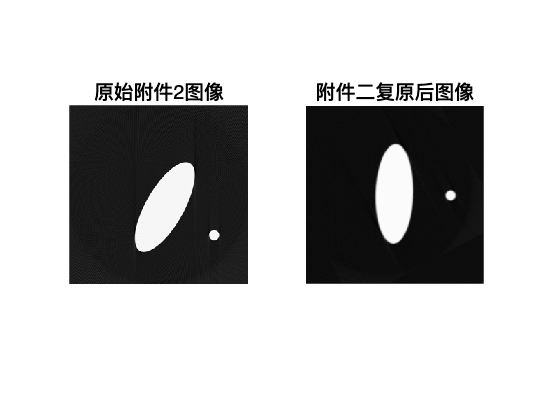

tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I2_translated = imwarp(I2, tform, 'OutputView', imref2d(size(I2)));

% 旋转图像，使得初始角度为 0
I2_rotated = imrotate(I2_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 计算 Radon 变换
R2_estimated = radon(I2_rotated, theta);

% 使用逆 Radon 变换复原图像
I2_reconstructed = iradon(R2_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I2, []);
title('原始附件2图像');

subplot(1,2,2);
imshow(I2_reconstructed, []);
title('附件二复原后图像');

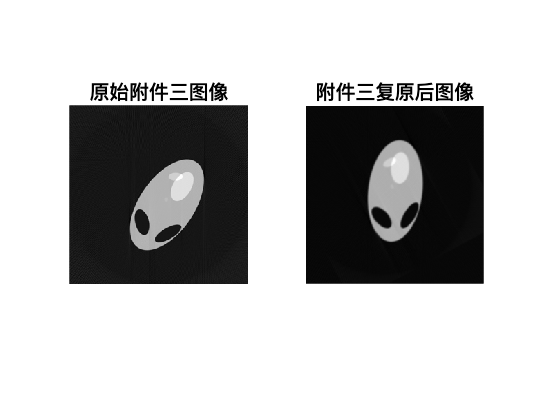


% I_reconstructed
F3 = iradon(File3, theta, 'linear', 'Ram-Lak', 1, 512);
I3 = imresize(F3,0.5);

% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I3) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I3_translated = imwarp(I3, tform, 'OutputView', imref2d(size(I3)));

% 旋转图像，使得初始角度为 0
I3_rotated = imrotate(I3_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 计算 Radon 变换
R3_estimated = radon(I3_rotated, theta);

% 使用逆 Radon 变换复原图像
I3_reconstructed = iradon(R3_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I3, []);
title('原始附件三图像');

subplot(1,2,2);
imshow(I3_reconstructed, []);
title('附件三复原后图像');

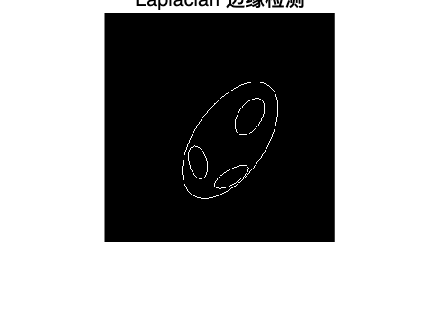

% 使用 Laplacian 算子进行边缘检测
edges_laplacian_raw = edge(I3, 'Sobel'); % 'log' 表示拉普拉斯-高斯算子
% 显示结果
figure;
imshow(edges_laplacian_raw);
title('Laplacian 边缘检测');

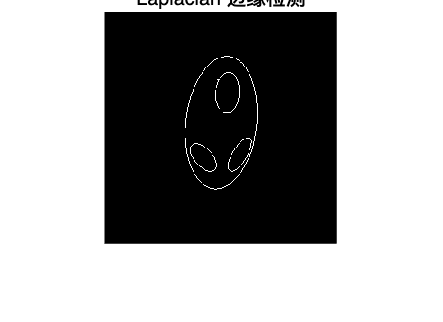

edges_laplacian = edge(I3_reconstructed, 'sobel'); % 'log' 表示拉普拉斯-高斯算子
% 显示结果
figure;
imshow(edges_laplacian);
title('Laplacian 边缘检测');

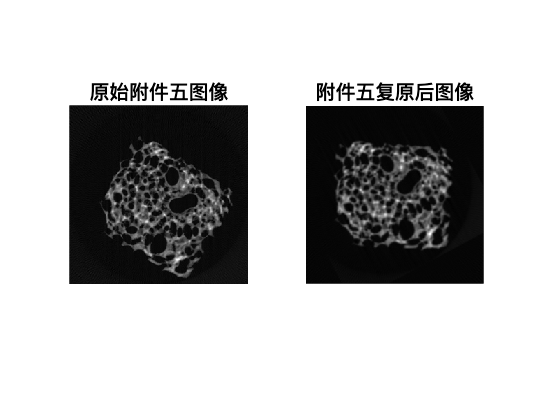


F5 = iradon(File5, theta, 'linear', 'Ram-Lak', 1, 512);
I5 = imresize(F5,0.5);

% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I5) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I5_translated = imwarp(I5, tform, 'OutputView', imref2d(size(I5)));

% 旋转图像，使得初始角度为 0
I5_rotated = imrotate(I5_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 计算 Radon 变换
R5_estimated = radon(I5_rotated, theta);

% 使用逆 Radon 变换复原图像
I5_reconstructed = iradon(R5_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I5, []);
title('原始附件五图像');

subplot(1,2,2);
imshow(I5_reconstructed, []);
title('附件五复原后图像');

I2_reconstructed(1,:) = [];
I2_reconstructed(end,:) = [];
I2_reconstructed(:,1) = [];
I2_reconstructed(:,end) = [];

I3_reconstructed(1,:) = [];
I3_reconstructed(end,:) = [];
I3_reconstructed(:,1) = [];
I3_reconstructed(:,end) = [];
writematrix(I2_reconstructed,"problem2.xlsx");
writematrix(I3_reconstructed,"problem3.xlsx");